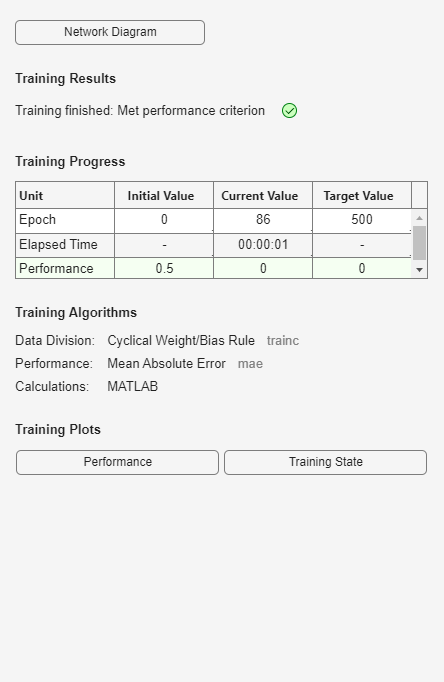

%福冈归属的感知器判别（变量除以标准差）
clear                                       %清理内存
P=[14.1865 14.7286 15.5418 16.9876 16.1744 14.7286 
2.8297 3.6757 4.1483 5.4669 4.9534 2.8472 
6.9131 6.5251 5.4016 5.3484 5.7834 3.8775 
-3.1628 -2.6561 -1.4586 -0.7523 -0.6909 -0.7062 
0.8319 1.2260 2.0142 3.5029 3.2840 2.4521]; %训练样本的输入变量
T=[1 1 0 0 0 1];                            %目标输出
Q=[14.6383 4.3525 6.2591 -1.2590 2.7148]';  %待判样品（福冈）
net=newp(minmax(P),1);                      %创建一个感知器网络
net.trainParam.epochs=500;                  %指定最大训练次数
net=train(net,P,T);                         %网络训练

Yp=sim(net,P)                               %训练样品的预报结果

Yp =      1     1     0     0     0     1


Y=sim(net,Q)                                %待判样品的归类结果

Y = 0